Mode number: 2
kx : 0.436
Error of calculation: 0.000
Power: 1.000


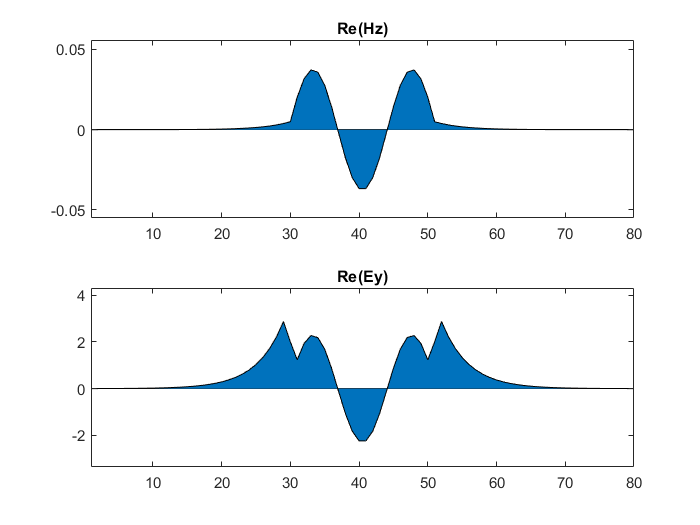

Mode number: 3
kx : 0.297
Error of calculation: 0.000
Power: 1.000


clear all;
close all;
clc

eps = ones([40 80]);
eps(:, 30:50) = 12.25;
eps(3 : end-2, 3 : end-2) = 9.0;

c = 3 * 10^8;
omega = 0.15 * c;

prob = form(omega, eps, [1 12.25], [2 3], 'pml', 'pos');

iter_num 	sub 	phy_res 	grad
      1: 	(x) 	9.499e-06 	2.825e-03
      1: 	(y) 	6.715e-06 	2.209e-03
      2: 	(x) 	5.739e-06 	2.048e-03
      2: 	(y) 	5.304e-06 	2.058e-03
      3: 	(x) 	4.954e-06 	1.986e-03
      3: 	(y) 	4.673e-06 	2.014e-03
      4: 	(x) 	4.432e-06 	1.946e-03
      4: 	(y) 	4.233e-06 	1.976e-03
      5: 	(x) 	4.060e-06 	1.914e-03
      5: 	(y) 	3.909e-06 	1.939e-03
      6: 	(x) 	3.778e-06 	1.885e-03
      6: 	(y) 	3.660e-06 	1.904e-03
      7: 	(x) 	3.554e-06 	1.857e-03
      7: 	(y) 	3.454e-06 	1.873e-03
      8: 	(x) 	3.363e-06 	1.829e-03
      8: 	(y) 	3.278e-06 	1.842e-03
      9: 	(x) 	3.199e-06 	1.800e-03
      9: 	(y) 	3.122e-06 	1.812e-03
     10: 	(x) 	3.051e-06 	1.772e-03
     10: 	(y) 	2.983e-06 	1.783e-03
     11: 	(x) 	2.920e-06 	1.744e-03
     11: 	(y) 	2.859e-06 	1.755e-03
     12: 	(x) 	2.801e-06 	1.718e-03
     12: 	(y) 	2.744e-06 	1.729e-03
     13: 	(x) 	2.690e-06 	1.694e-03
     13: 	(y) 	2.637e-06 	1.704e-03
     14: 	(x) 	2.587e-06 	1.670e-03

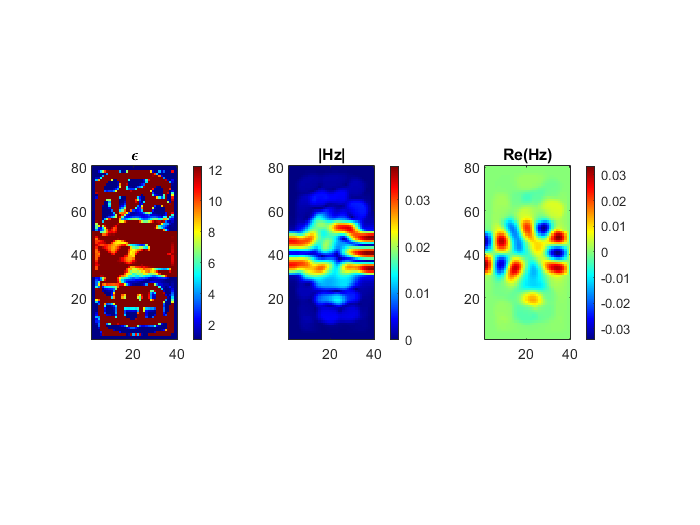

200 iterations completed in 324.9 second.


eps = optimize(prob, 200, 1e-4);

Input mode analysis
 Mean total power: 0.97
 Error: 0.00
 Mean mode power: 0.97
 Error: 0.00
 Ratio: 1.00
 
Output mode analysis
 Mean total power: 0.91
 Error: 0.00
 Mean mode power: 0.89
 Error: 0.01
 Ratio: 0.98
 
Conversion effeciency: 0.91

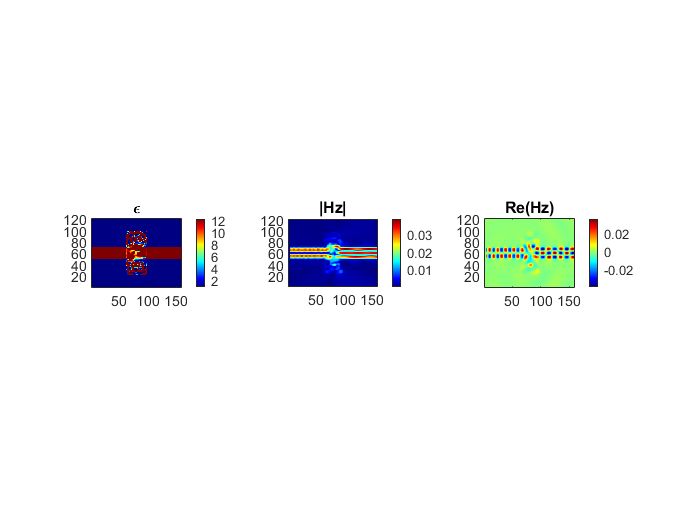

thick = [60, 60, 20, 20];
[Ex, Ey, Hz] = simulate(eps, thick, prob);

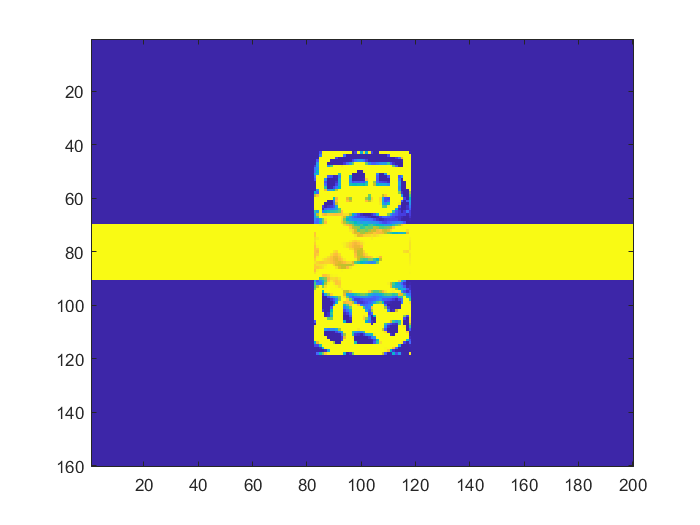

thick_2 = [80, 80, 40, 40];
eps_2 = pad_eps(eps, thick_2);
file_path = 'txt\n_f_23.txt';

% export the eps
fileID = fopen(file_path, 'w+');

[y, x, eps_f] = find(eps_2');
y = max(y) - y;
n = sqrt(eps_f);
result = [x'; y'; n'];

fprintf(fileID, '%e %e %e\n', result);
fclose(fileID);

% check the output result
fileID = fopen(file_path, 'r');
A = fscanf(fileID, '%e %e %e', [3, inf]);
A = A';
eps_3 = reshape(A(:, 3), [120 + 40, 160 + 40]);
figure();
imagesc(eps_3)

fclose(fileID);